%%
% Dividing the data into train and test data
cv1 = cvpartition(size(X,1),'HoldOut',0.3);
idx1 = cv1.test;
dataTrain1=X(~idx1,:);
dataTest1=X(idx1,:);
testing1=dataTest1(1:end,1:end-1);


%%
% Multiple Linear Regression on all features except date 
tic
mdl_lm = stepwiselm(dataTrain1,"interactions")

1. Removing quarter:department, FStat = NaN, pValue = NaN
2. Removing quarter:day, FStat = NaN, pValue = NaN
3. Removing quarter:team, FStat = NaN, pValue = NaN
4. Removing quarter:targeted_productivity, FStat = NaN, pValue = NaN
5. Removing quarter:smv, FStat = NaN, pValue = NaN
6. Removing quarter:wip, FStat = NaN, pValue = NaN
7. Removing quarter:over_time, FStat = NaN, pValue = NaN
8. Removing quarter:incentive, FStat = NaN, pValue = NaN
9. Removing quarter:idle_time, FStat = NaN, pValue = NaN
10. Removing quarter:idle_men, FStat = NaN, pValue = NaN
11. Removing quarter:no_of_style_change, FStat = NaN, pValue = NaN
12. Removing quarter:no_of_workers, FStat = NaN, pValue = NaN
13. Removing quarter, FStat = NaN, pValue = NaN
14. Removing department:day, FStat = NaN, pValue = NaN
15. Removing department:team, FStat = NaN, pValue = NaN
16. Removing department:targeted_productivity, FStat = NaN, pValue = NaN
17. Removing department:smv, FStat = NaN, pValue = NaN
18. Removing department:

mdl_lm = Linear regression model:
    actual_productivity ~ 1 + idle_men + quarter*wip + quarter*no_of_workers + department*targeted_productivity + department*smv + department*over_time + department*no_of_workers + targeted_productivity*wip + targeted_productivity*incentive + targeted_productivity*no_of_workers + smv*incentive + smv*no_of_style_change + over_time*incentive + idle_time*no_of_workers

Estimated Coefficients:
                                                   Estimate        SE        tStat        pValue  
                                                  __________    ________    ________    __________

    (Intercept)                                     -0.17169     0.26374    -0.65098       0.51525
    quarter_Quarter2                               -0.085913    0.036298     -2.3669      0.018176
    <s

toc

Elapsed time is 58.785862 seconds.



% Predicting responses
prediction1=predict(mdl_lm,testing1);
errs1 = prediction1 - dataTest1.actual_productivity;
sq_errs1=(errs1.^2);
mse1=mean(sq_errs1);
rmse1=sqrt(mse1);
disp(rmse1);

      0.19281



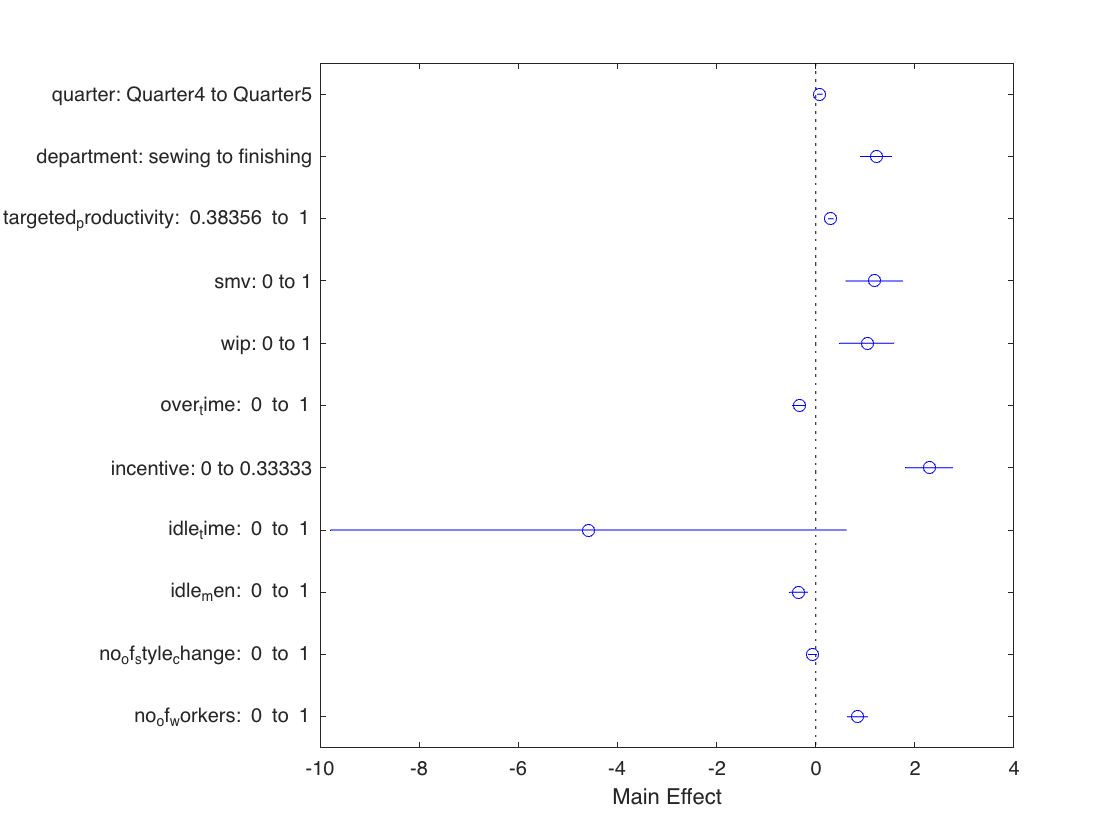


%%
% Few data visualisations to understand the interaction effect in the data
figure
plotEffects(mdl_lm)

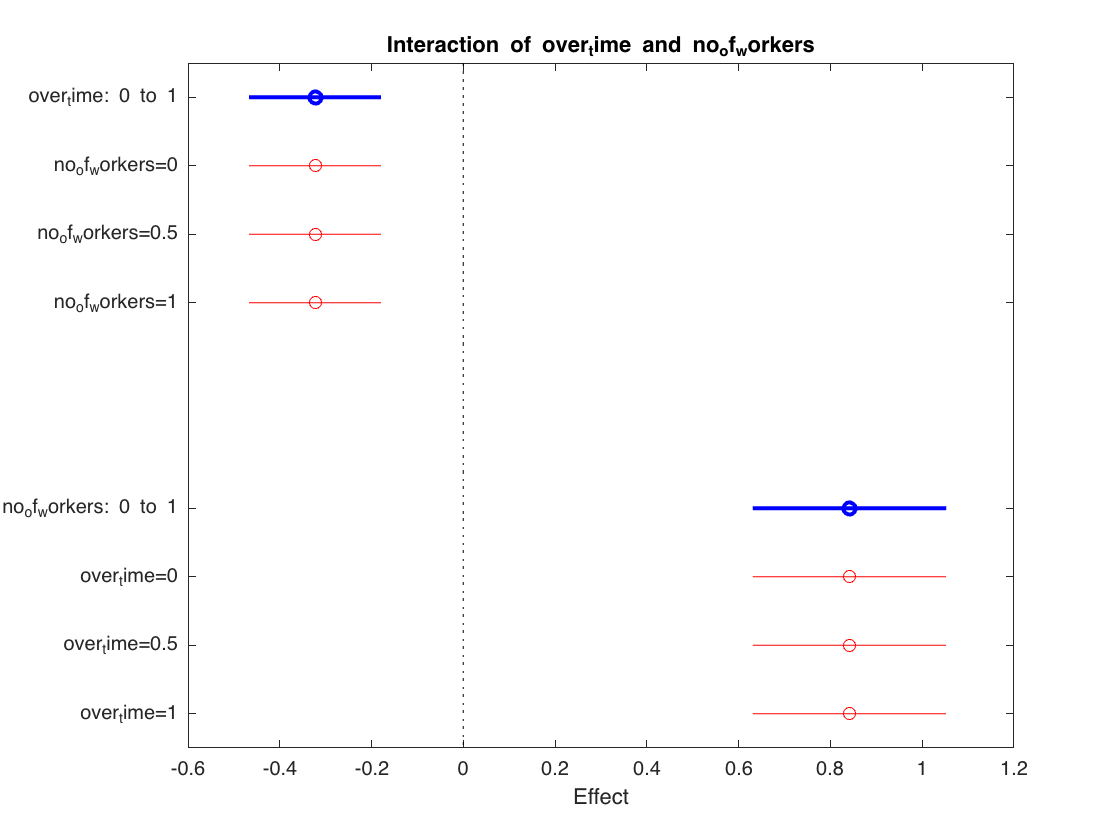

plotInteraction(mdl_lm,'over_time','no_of_workers')

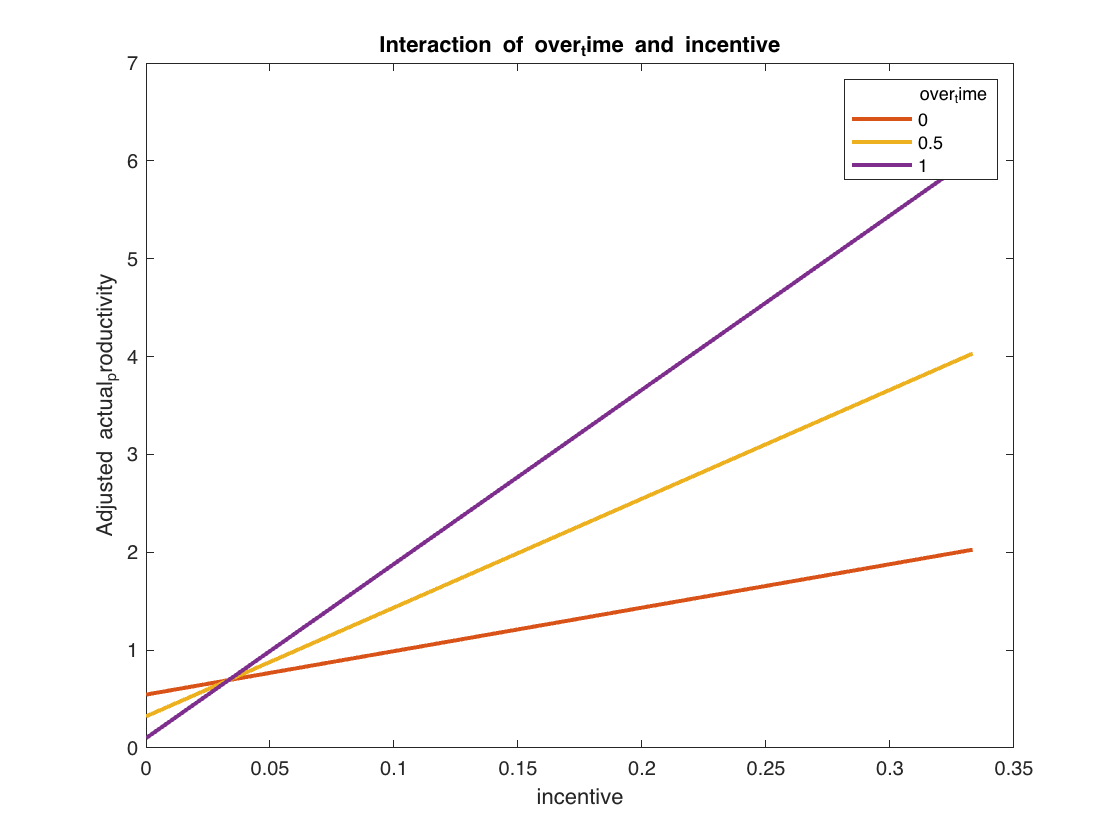

plotInteraction(mdl_lm,'over_time','incentive','predictions')

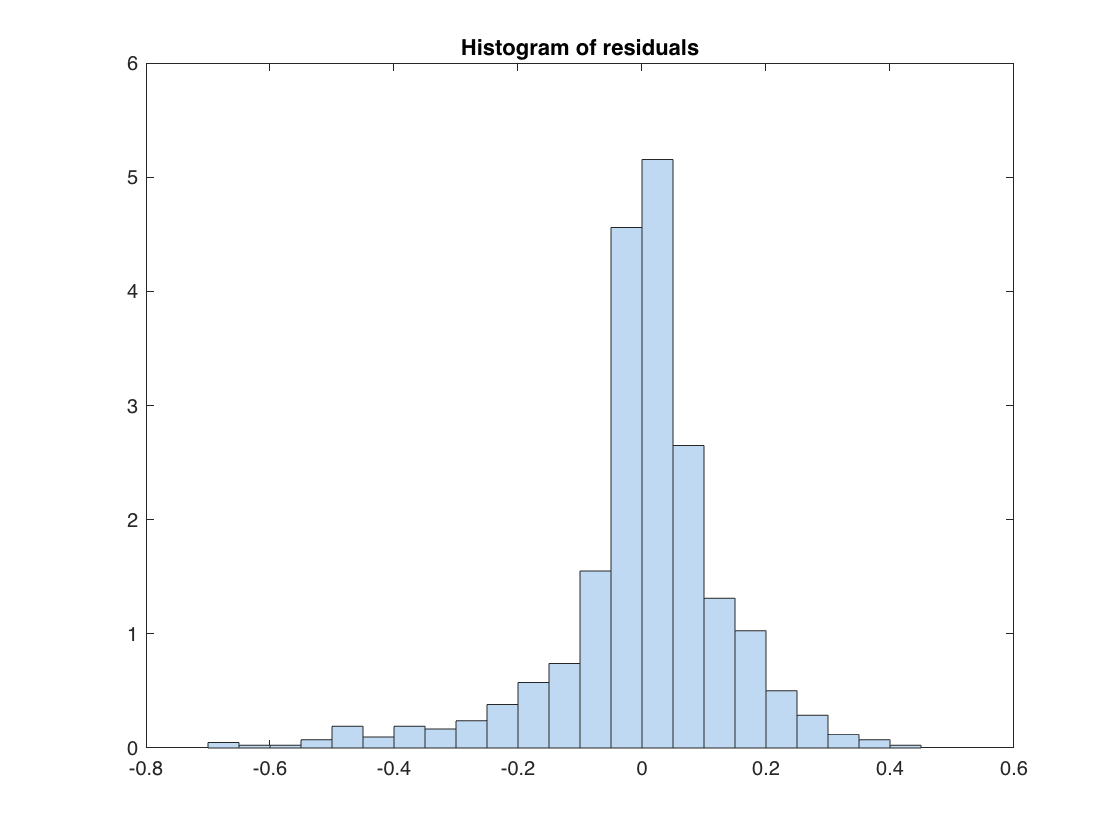

plotResiduals(mdl_lm)

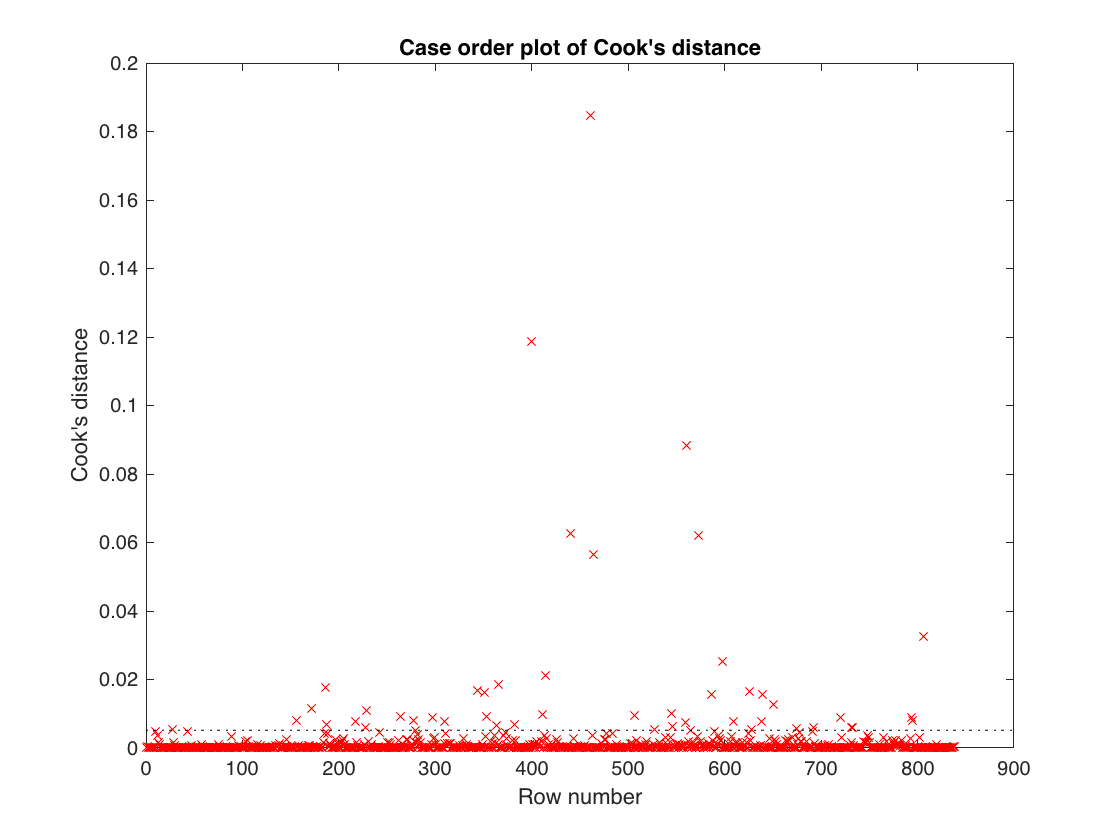


%%
%Finding the outliers as shown in the residual plot
plotDiagnostics(mdl_lm,'cookd')

out=find((mdl_lm.Diagnostics.CooksDistance)>21*mean(mdl_lm.Diagnostics.CooksDistance))

out =    400
   440
   461
   464
   560
   573
